CS 567 (HW4)

Sparsh Agarwal

9075905142

Q1. (a) 

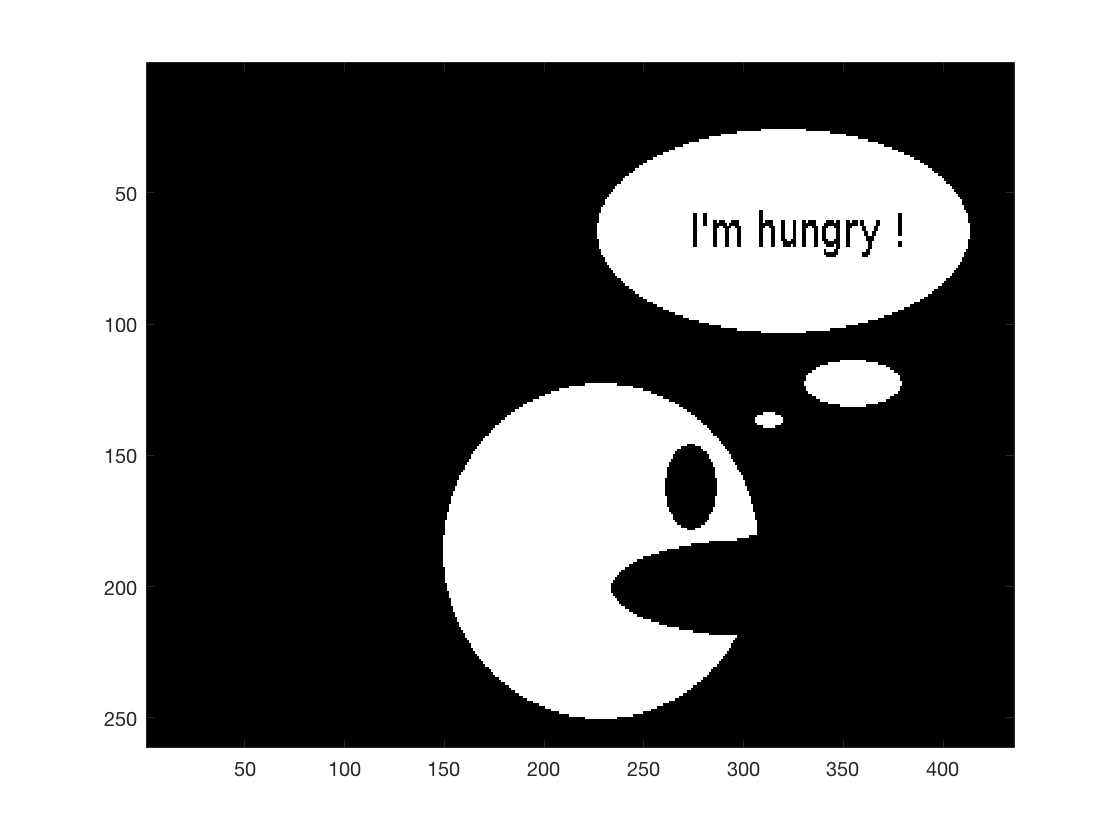

% script from W. Birkfellner, M. Figl, J. Hummel: "Medical Image Processing - A Basic Course", copyright 2010 by Taylor & Francis
clear;
path='/Users/sparshagarwal/OneDrive/Spring 2018/CS 567/AMIP_II_CD/LessonData/6_Segmentation/';
% Change to the AMIP_II_CD/LessonData/6_Segmentation directory
img = double(imread(sprintf('%s/PACMAN_THINKS.jpg', path)));

% Let's binarize to make this a simpler example
img(img<=250) = 0;
img(img>250) = 1;

figure
colormap(gray)
imagesc(img)


% Slightly different approach
% I binarized the image (see author's example for when it isn't binary)
% work on extending around all identified pixels at once

% create a vector of x and y coordinates of all pixels already identified
% to be part of the region.  To start we only have 1 of each
xmax = size(img,1);
ymax = size(img, 2);

% % initialize at this location
% reg_locx = [164];
% reg_locy = [155];
% 
% % generate values to initialize while loop
% old_reg_locx = [];
% old_reg_locy = [];
% 
% % I'll store the segment here
seg_loc = 0*img;

seg_label = 1;
[row,col] = find(img==1 & seg_loc==0, 1);

while ~isempty(row)
    
% I'll use this to control the segment number used to identify the segment
% in seg_loc.  This will become more useful in the homework, since you'll
% create multiple segments
seg_label = seg_label+1;
old_reg_locx = [];
old_reg_locy = [];
reg_locx = row(1);
reg_locy = col(1);

while length(reg_locx)~=length(old_reg_locx)  % suffices to only check x
    old_reg_locx = reg_locx;
    old_reg_locy = reg_locy;
    % First create the "grown" coordinates
    reg_locx = [old_reg_locx; old_reg_locx; old_reg_locx; old_reg_locx+1;...
        old_reg_locx-1];
    reg_locy = [old_reg_locy; old_reg_locy-1; old_reg_locy+1; old_reg_locy;...
        old_reg_locy];
    % remove values out of range
    bad = reg_locx<1 | reg_locx>xmax | reg_locy<1 | reg_locy>ymax;
    reg_locx = reg_locx(bad==0);
    reg_locy = reg_locy(bad==0);
    % remove duplicates 
    coord_all = [reg_locx, reg_locy];
    coord_all = unique(coord_all, 'rows');
    % MATLAB can only extract values from a matrix according to multiply
    % (x,y) locations if you first translate to the linear index
    loc_linear = sub2ind(size(img), coord_all(:,1), coord_all(:,2));
    seg_loc(loc_linear) = seg_label*img(loc_linear);
    % Since we already converted img to 0s and 1s, the right hand side of
    % the above will only create labels for the pixels that should be
    % labeled
    % Last, regenerate the x,y indices that made it to the end
    [reg_locx, reg_locy] = find(seg_loc == seg_label);
end
% img(loc_linear) = seg_label;
% figure
% imagesc(seg_loc)
% figure
% imagesc(img)
[row,col] = find(img==1 & seg_loc==0, 1);
seg_label
end

seg_label = 2

seg_label = 3

seg_label = 4

seg_label = 5

seg_label = 6

%  figure
% %  imagesc(seg_loc)
%  imagesc(img)
seg_label

seg_label = 6

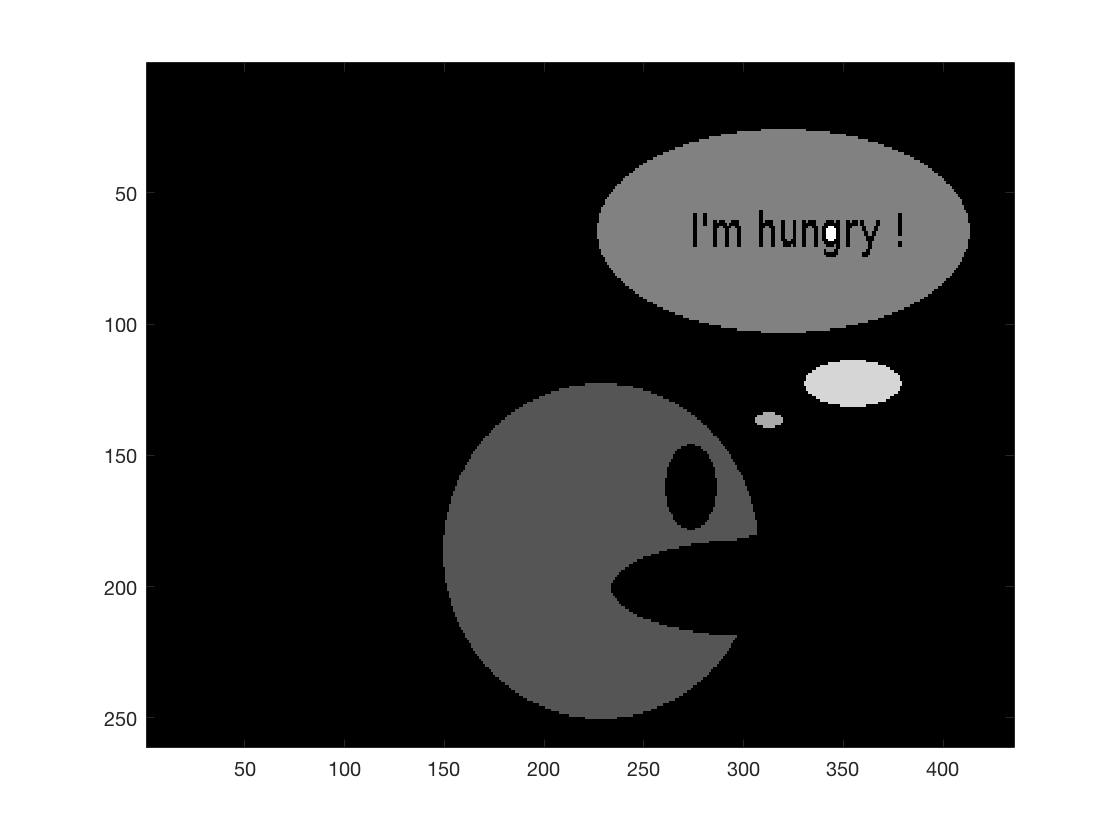

imagesc(seg_loc)

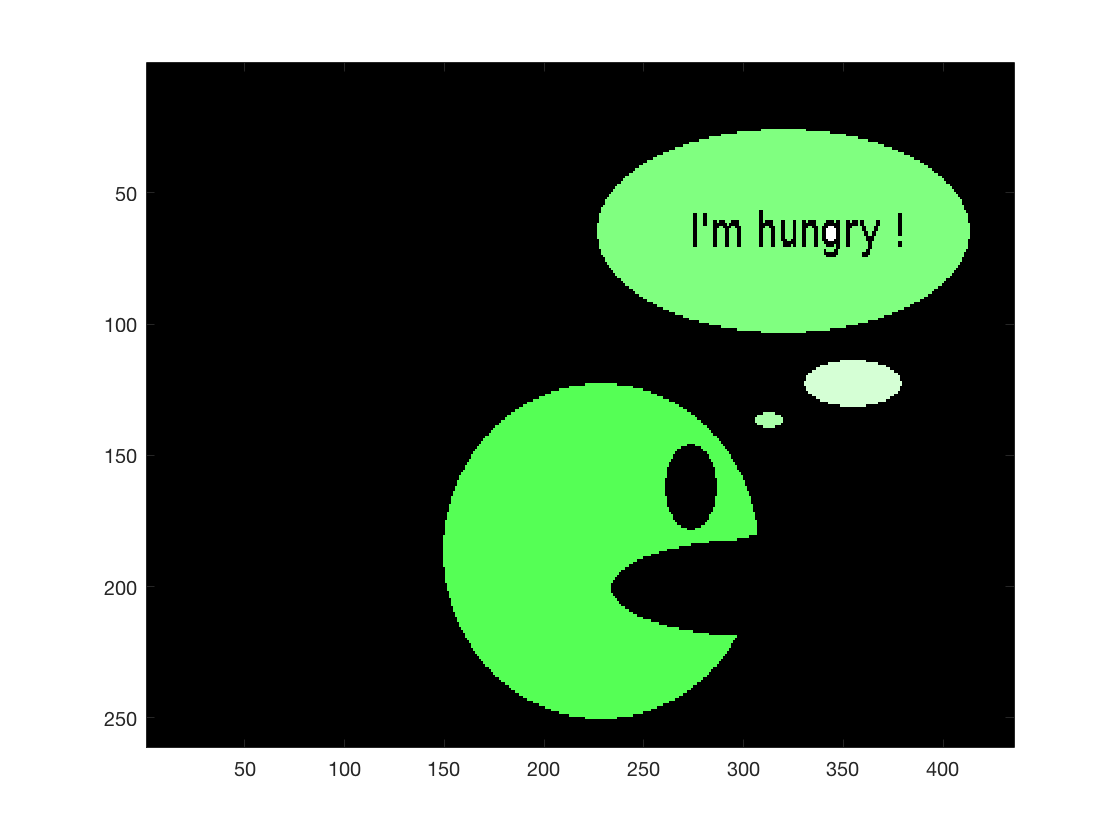

 imagesc(imfuse(img, seg_loc))